# Ejercicio 2.2: Modelo de convección atmosférica de Lorenz

**a)**

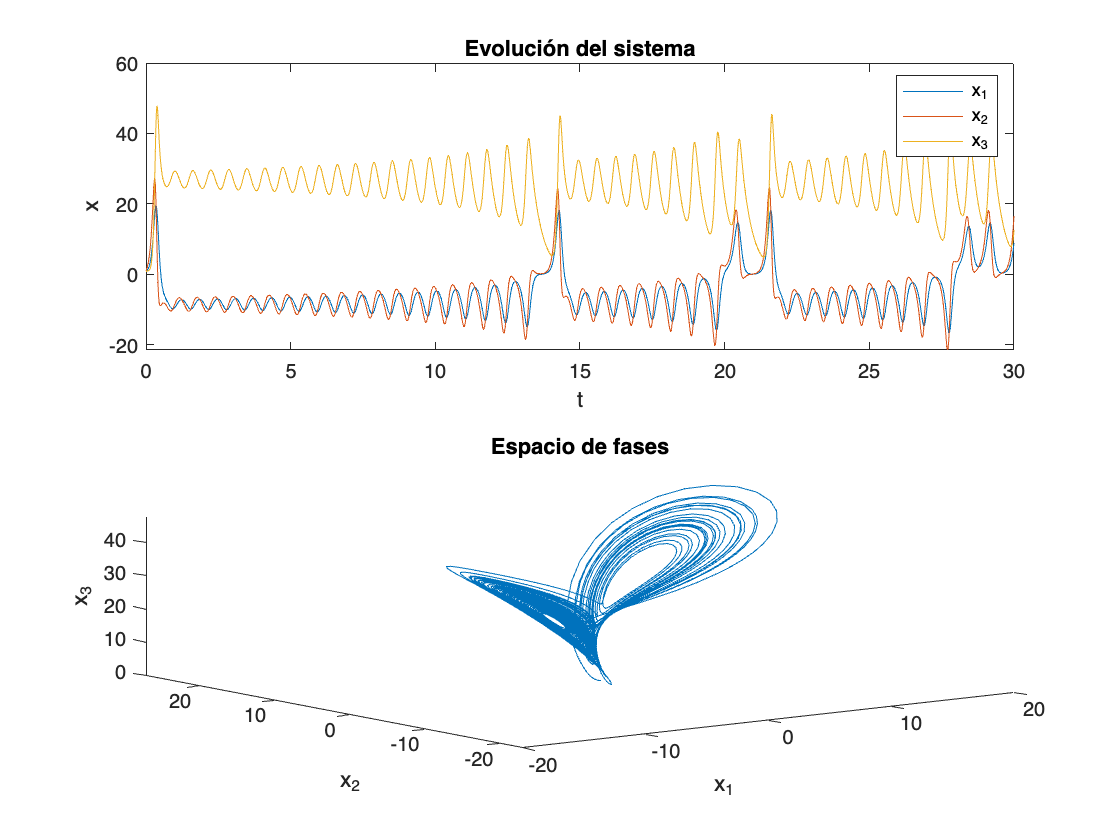

clear all; close all; clc;
[s, b, r] = deal(10, 8/3, 28); %Soluciones caóticas

x0 = [1; 1; 1];
tspan = [0, 60];

[t, x] = ode45(@(t, x)lorenz(t, x, s, b, r), tspan, x0);

figure();
subplot(2, 1, 1)
plot(t, x)
title("Evolución del sistema")
legend("x_1", "x_2", "x_3")
ylabel("x")
xlabel("t")
xlim([0, 30])

subplot(2,1,2)
plot3(x(:,1), x(:,2), x(:,3));
title("Espacio de fases")
xlabel("x_1")
ylabel("x_2")
zlabel("x_3")

**b)**

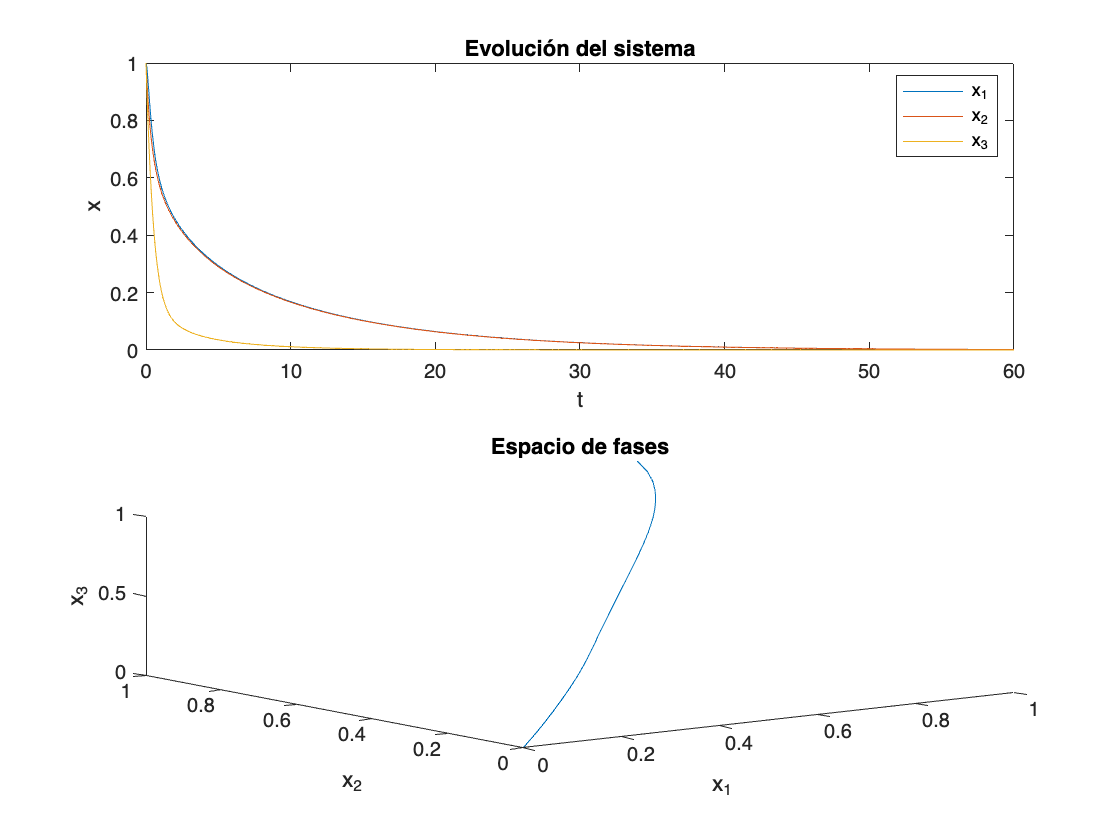

%Compruebo que converge para rho < 1

r = 0.9;
[t, x] = ode45(@(t, x)lorenz(t, x, s, b, r), tspan, x0);

figure();
subplot(2, 1, 1)
plot(t, x)
title("Evolución del sistema")
legend("x_1", "x_2", "x_3")
ylabel("x")
xlabel("t")

subplot(2,1,2)
plot3(x(:,1), x(:,2), x(:,3));
title("Espacio de fases")
xlabel("x_1")
ylabel("x_2")
zlabel("x_3")

%El punto de equilibrio es (0,0,0). Se puede comprobar que el sistema
%converge al origen tanto en la gráfica de fases como en la evolución temporal individual de cada componente. 

Los puntos de equilibrio siguen las ecuaciones


$$0 = \sigma x_1 - \sigma x_2 \Rightarrow x_1  = x_2 \\

0 = x_1 (\rho - x_3) - x_2 \Rightarrow x_1(\rho - 1 - x_3) = 0\\

0 = x_1x_2 - \beta x_3 \Rightarrow x_1 = \pm \sqrt{\beta x_3}$$


Ahora bien, si rho es menor que uno, solo valdrá la solución 


$$x_1 = x_2 = x_3 = 0$$


pero si es mayor, las soluciones serán


$$x_1 = x_2 = x_3 = 0$$


y


$$x_3 = \rho - 1 \\
x_1 = x_2 = \pm \sqrt{\beta(\rho - 1)}$$


Nótese que para este cálculo se ha considerado que beta es positivo (en concreto, el enunciado indica dejar este parámetro igual a 8/3). En el caso de que rho sea igual a 1 ambas soluciones son equivalentes y devuelven el origen. Por tanto, rho = 1 es el punto en el que el sistema pasa de tener un punto de equilibrio (0, 0, 0) a tener 3:$(0, 0, 0), (\sqrt{\beta(\rho - 1)}\mbox{, }\sqrt{\beta(\rho - 1)}, \rho - 1) \mbox{ y }  (-\sqrt{\beta(\rho - 1)}, -\sqrt{\beta(\rho - 1)}, \rho - 1)$.

De modo que el sistema tiene una bifurcación *pitchfork* en rho = 1. 

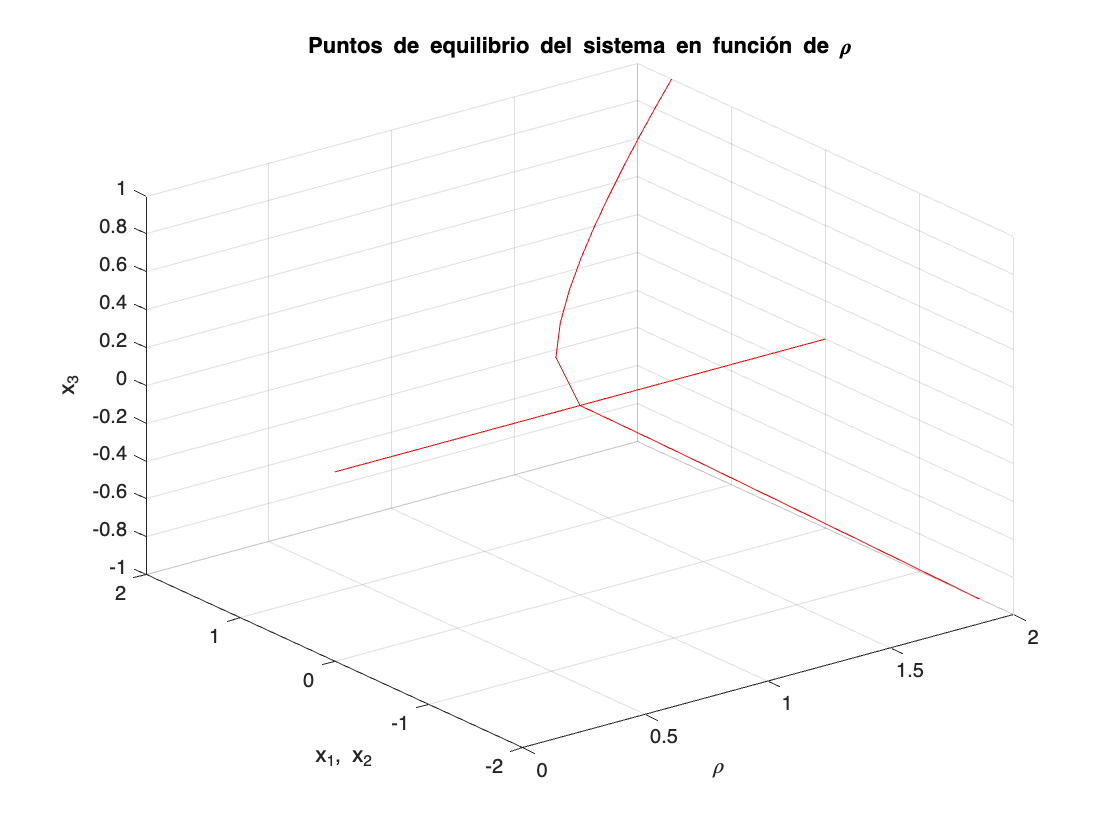

r = 1:0.1:2;

x1 = @(r) (8/3 .* (r - 1)).^.5;
x3 = @(r) r - 1;
figure();
plot3(r, r.*0, r.*0, "r"); hold on; grid on;
plot3(r, x1(r), x3(r), "r");
plot3(r, -x1(r), -x3(r), "r");
plot(r - 1, r .* 0, "r");
title("Puntos de equilibrio del sistema en función de \rho")
xlabel("\rho")
ylabel("x_1, x_2")
zlabel("x_3")

%Voy a probar el quiver

%[x1, x2, x3] = deal(-1:0.1:1);
%[x1m, x2m, x3m] = meshgrid(x1, x2, x3);

%xdot1m = s .* (x2m - x1m);
%xdot2m = x1m .* (repelem(1, length(x3m)) - x3m) - x2m;
%xdot3m = x1m .* x2m - b .* x3m;

%figure();
%quiver3(x1m, x2m, x3m, xdot1m, xdot2m, xdot3m);
%axis("tight")



function xdot = lorenz(t, x, s, b, r)

    xdot(1,1) = s*(x(2,1) - x(1,1));
    xdot(2,1) = x(1,1) * (r - x(3,1)) - x(2,1);
    xdot(3,1) = x(1,1) * x(2,1) - b * x(3,1);
end